# **Tutorial: System of non-linear equations**

**Numerical Programming: Y.-K. Kim**

Mod. 2024.10

# **Exercise 1**

## Problem 

Solve the following system of non-linear equations


$$f_1(x,y)=y-0.5(e^{(x/2)}+e^{(-x/2)})=0$$



$$f_2(x,y)=9x^2+25y^2-225=0$$


### TUTORIAL: MATLAB

close all, clear all
clc

type myFuncEx1_student.m

function F=myFuncEx1_student(Z)
    x = Z(1); 
    y = Z(2);

    F=zeros(2,1);

    F(1) = y-0.5*(exp(x/2)+exp(-x/2)) ;
    F(2) = 9*x^2+25*y^2-225;
end


Need to install **optimization toolbox: fsolve()**

fun=@myFuncEx1_student;
x_init = [2.5,2];
% x_est = fsolve(fun,x_init)

## Exercise:

**Define functions that returns vector F(x) and matrix J(x).**

- Matrix **myF****unc**(Matrix X,)  // X: vector in. ReturnsVector F  (nx1)

- Matrix **myJacob**(Matrix X) // X: vector in.  Returns Matrix J  (nxn)

**Define system non-linear solver**

- Matrix **newtonRoots****(**Matrix X0, float tol**)** 

-       //  input - vector **x0**, float tol  

-      // returns  vector**X****N**   (nx1)

### Solve for the solution with Newton-rhapson

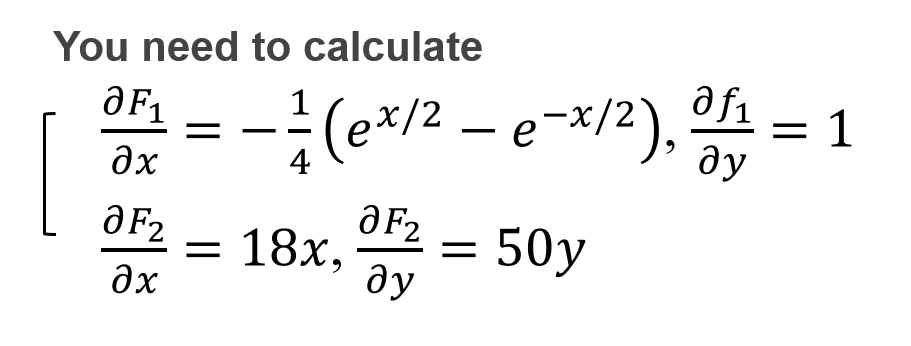

% Initial condition
tol=0.0001;
Zinit =  [2.5;2];
Z=Zinit;


for k=1:20
    
    F=myFuncEx1_student(Z);

    % Define J
    J=myJacobEx1_student(Z);    

    % H=inv(J)*(-F);  % do not use J inverse. Instead,  use
    % JH=-F  % Gauss Elimination or LU    
    % C-programing: solve for Ax=b
    H = - inv(J)*(F);

    % Update Z 
    Z=Z+H;

    loss=norm(myFuncEx1_student(Z));
    fprintf("iter =%d \t x=%0.3f \t y=%0.3f \t loss=%0.3f\n",k,Z(1),Z(2),loss)
    
    if (loss<tol)
        break;
    end
end

iter =1 	 x=3.139 	 y=2.400 	 loss=7.674
iter =2 	 x=3.034 	 y=2.385 	 loss=0.104
iter =3 	 x=3.031 	 y=2.386 	 loss=0.000


# **Exercise 2**

## Problem 

Solve for  rotation angle (θ) and translation [Δx, Δy] 

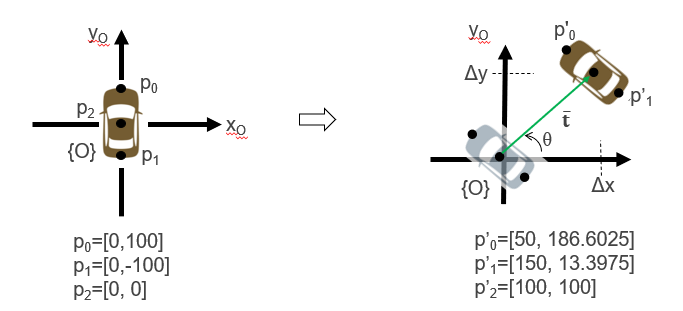

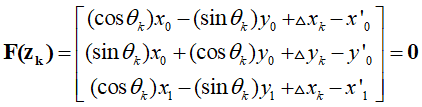

Solution =  [θ=30 deg (0.5236),   Δx =100mm , Δy= 100mm ]

### How to create Jacobian Matrix

You need to install **symbolic math toolbox**

%% Symbols: to get F and J
% You need to install symbolic math toolbox
syms th dx dy  P0x P0y P1x P1y P0x_new P0y_new P1x_new P1y_new

t=[dx; dy];
R=[cos(th) -sin(th);sin(th) cos(th)];

P0_prev=[P0x;P0y];
P1_prev=[P1x;P1y];
P0_new=[P0x_new;P0y_new];
P1_new=[P1x_new;P1y_new];

F0=R*P0_prev+t-P0_new       % F0(R,t)=0

$$F0 = \left(\begin{array}{c} \mathrm{dx}-{\mathrm{P0x}}_{\mathrm{new}}+\mathrm{P0x}\,\cos\left(\mathrm{th}\right)-\mathrm{P0y}\,\sin\left(\mathrm{th}\right)\\ \mathrm{dy}-{\mathrm{P0y}}_{\mathrm{new}}+\mathrm{P0y}\,\cos\left(\mathrm{th}\right)+\mathrm{P0x}\,\sin\left(\mathrm{th}\right) \end{array}\right)$$

F1=R*P1_prev+t-P1_new       % F1(R,t)=0

$$F1 = \left(\begin{array}{c} \mathrm{dx}-{\mathrm{P1x}}_{\mathrm{new}}+\mathrm{P1x}\,\cos\left(\mathrm{th}\right)-\mathrm{P1y}\,\sin\left(\mathrm{th}\right)\\ \mathrm{dy}-{\mathrm{P1y}}_{\mathrm{new}}+\mathrm{P1y}\,\cos\left(\mathrm{th}\right)+\mathrm{P1x}\,\sin\left(\mathrm{th}\right) \end{array}\right)$$

% Select three equations
F=[F0(1);F0(2);F1(1)]

$$F = \left(\begin{array}{c} \mathrm{dx}-{\mathrm{P0x}}_{\mathrm{new}}+\mathrm{P0x}\,\cos\left(\mathrm{th}\right)-\mathrm{P0y}\,\sin\left(\mathrm{th}\right)\\ \mathrm{dy}-{\mathrm{P0y}}_{\mathrm{new}}+\mathrm{P0y}\,\cos\left(\mathrm{th}\right)+\mathrm{P0x}\,\sin\left(\mathrm{th}\right)\\ \mathrm{dx}-{\mathrm{P1x}}_{\mathrm{new}}+\mathrm{P1x}\,\cos\left(\mathrm{th}\right)-\mathrm{P1y}\,\sin\left(\mathrm{th}\right) \end{array}\right)$$


% This is the same as 
F =[P0x*cos(th) - P0y*sin(th) + dx - P0x_new 
    P0x*sin(th) + P0y*cos(th) + dy - P0y_new
    P1x*cos(th) - P1y*sin(th) + dx - P1x_new];
%simplify(F)


J=jacobian(F,[th dx dy])

$$J = \left(\begin{array}{ccc} -\mathrm{P0y}\,\cos\left(\mathrm{th}\right)-\mathrm{P0x}\,\sin\left(\mathrm{th}\right) & 1 & 0\\ \mathrm{P0x}\,\cos\left(\mathrm{th}\right)-\mathrm{P0y}\,\sin\left(\mathrm{th}\right) & 0 & 1\\ -\mathrm{P1y}\,\cos\left(\mathrm{th}\right)-\mathrm{P1x}\,\sin\left(\mathrm{th}\right) & 1 & 0 \end{array}\right)$$

%simplify(J)

### Solve for the solution with Newton Rhapson

% Initial condition
tol=0.00001;
Zinit=[25/180*pi, 90, 90]';
Z=Zinit;

for k=1:20
    %th=Z(1); dx=Z(2); dy=Z(3);
    F=myFuncEx2_student(Z)
    J=myJacobEx2_student(Z)
    
    % H=inv(J)*(-F);  % do not use J inverse. Instead,  use
    % JH=-F  % Gauss Elimination or LU    
    H=inv(J)*(-F);
    
    % Update Z 
    Z=Z+H;
    
    loss=norm(myFuncEx2_student(Z));
    fprintf("iter =%d \t theta=%0.3f \t dX=%0.3f \t  dY=%0.3f \t loss=%0.3f\n",k,Z(1),Z(2),Z(3),loss)
    if (loss<tol)
        break;
    end
end

F =    -2.2618
   -5.9717
  -17.7382


J =   -90.6308    1.0000         0
  -42.2618         0    1.0000
   90.6308    1.0000         0


iter =1 	 theta=0.522 	 dX=100.000 	  dY=99.580 	 loss=0.399


F =     0.1633
   -0.3258
   -0.1633


J =   -86.6966    1.0000         0
  -49.8367         0    1.0000
   86.6966    1.0000         0


iter =2 	 theta=0.524 	 dX=100.000 	  dY=100.000 	 loss=0.000


F = 1.0e-03 *

    0.0886
   -0.1538
   -0.0886


J =   -86.6026    1.0000         0
  -49.9999         0    1.0000
   86.6026    1.0000         0


iter =3 	 theta=0.524 	 dX=100.000 	  dY=100.000 	 loss=0.000


Validate your answer

th=Z(1) * (180 / pi)

th = 30.0000

dx=Z(2)

dx = 100

dy=Z(3)

dy = 100.0000

t=[dx; dy];
R=[cos(th) -sin(th);sin(th) cos(th)];

P0=[0,100]';
P1=[0,-100]';
P0new=R*P0+t       

P0new =   198.8032
  115.4251


P1new=R*P1+t         

P1new =     1.1968
   84.5748


**Check with MATLAB function output**

fun=@myFuncEx2_student;
Zinit_mat=[25/180*pi, 90, 90]';
Zest_mat = fsolve(fun,Zinit_mat)


방정식을 풀었습니다.

함수 허용오차 값을 기준으로 보면
함수 값 벡터가 0에 가깝고
기울기를 기준으로 보면 문제가 정칙적인 것 같기 때문에 fsolve이(가) 완료되었습니다.

<중지 기준 세부 정보>


Zest_mat =     0.5236
  100.0000
  100.0000


Validate  your answer

th=Zest_mat(1);
dx=Zest_mat(2);
dy=Zest_mat(3);
t=[dx; dy];
R=[cos(th) -sin(th);sin(th) cos(th)];

P0=[0,100]';
P1=[0,-100]';
P0new=R*P0+t      

P0new =    50.0000
  186.6025


P1new=R*P1+t     

P1new =   150.0000
   13.3974
